# **META 1**

1. e 2. Crie uma estrutura de dados (por exemplo, uma tabela) e guarde as seguintes informações relativas a cada áudio: a. diretório do áudio; b. nome do ficheiro (com extensão); c. participante; d. dígito; e. número da repetição. Desenvolva código para importação dos sinais de áudio e guarde o valor da taxa de amostragem e os sinais na estrutura de dados criada.

addpath('functions');

pastaAudios = 'audios';  
audios = dir(fullfile(pastaAudios, '*.wav'));

numeroAudios = length(audios);

%Estrutura de dados que armazena todas as informacoes relevantes dos 500 audios.
dados = struct();
           
%Extração das informações presentes nos ficheiros de audio.           
for i = 1:numeroAudios                                   
    nomeFicheiro = audios(i).name;
    diretorio = fullfile(pastaAudios, nomeFicheiro);
    
    partesNome = split(nomeFicheiro, '_'); 
    
    digito = str2double(partesNome{1});      
    participante = partesNome{2};  
    
    partesRepeticao = split(partesNome{3}, '.');  
    repeticao = str2double(partesRepeticao{1});
    
    [sinal, taxaAmostragem] = audioread(diretorio);

    dados(i).('diretorio') = diretorio;
    dados(i).('nomeFicheiro') = nomeFicheiro;
    dados(i).('participante') = participante;
    dados(i).('digito') = digito;
    dados(i).('repeticao') = repeticao;
    dados(i).('sinal') = sinal;
    dados(i).('taxaAmostragem') = taxaAmostragem;
end

%Apenas para ser apresentavel.
tabela = struct2table(dados); 
tabela = sortrows(tabela, ["digito" "repeticao"]);
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem
    ______________________    _______________    ____________    ______    _________    ________________    ______________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {33565×1 double}        48000     
    {'audios\0_33_1.wav' }    {'0_33_1.wav' }       {'33'}         0           1        {26896×1 double}        48000     
    {'audios\0_33_2.wav' }    {'0_33_2.wav' }       {'33'}         0           2        {33859×1 double}        48000     
    {'audios\0_33_3.wav' }    {'0_33_3.wav' }       {'33'}         0           3        {36880×1 double}        48000     
    {'audios\0_33_4.wav

3. Reproduza e represente graficamente um exemplo dos sinais importados, identificando o dígito e o número da repetição a que cada um corresponde, e indicando o eixo horizontal com o tempo em segundos.

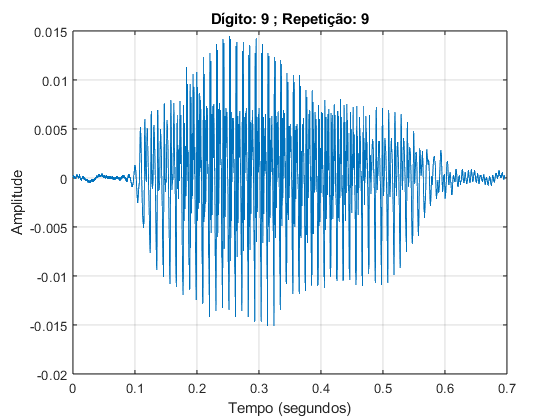

i = 500; %i = input('Linha: '); 
audio = dados(i);
plotarGrafico(audio);

4. e 5. Uma estratégia que pode melhorar a diferenciação entre dígitos é fazer uma etapa de préprocessamento para garantir que todos os ficheiros têm a mesma duração e intervalo de amplitude. Para isso deverá implementar os seguintes passos: 

-Retirar o “silêncio” inicial dos sinais, de forma a garantir que todos começam exatamente ao mesmo tempo (por exemplo, através do estudo da Energia do sinal ao longo do tempo).

 -Normalizar a amplitude com base na amplitude máxima e mínima das amostras. Isto garante que os problemas usuais da gravação do som (por exemplo, a distância da pessoa ao microfone) não interferem na análise. 

-Adicionar (ou retirar) silêncio no fim dos ficheiros para garantir que todos têm a mesma duração total. Guarde os sinais após o pré-processamento na estrutura de dados criada no ponto 1.

Para os sinais obtidos após o pré-processamento, repita o ponto 3. 

duracao = 0.8 %Duracao desejada

duracao = 0.8000

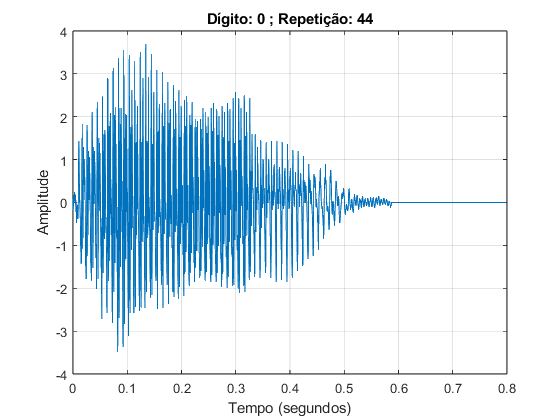

limiteEnergia = 0.001; %Valor de energia minima utilizado para detetar quando o ator começa a falar.

for i = 1:numeroAudios
    sinal = dados(i).sinal;
    tamanhoAudio = duracao * dados(i).taxaAmostragem;
    
    % Remover silêncio no início.
    energia = movsum(abs(sinal).^2, 1000); %1000 em 1000 amostras                       
    indiceInicio = find(energia > limiteEnergia, 1, 'first');
    sinal = sinal(indiceInicio:end);  

    % Normalizar a amplitude do sinal.
    sinal = (sinal - mean(sinal)) / std(sinal);                                   

    % Colocar a mesma duração para todos os audios.
    if length(sinal) < tamanhoAudio                               
        sinal = [sinal; zeros(tamanhoAudio - length(sinal), 1)];
    else
        sinal = sinal(1:tamanhoAudio);
    end

    dados(i).sinal = sinal;
end

%Apresentar audio após processamento.
i = 40; %i = input('Linha: '); 
audio = dados(i);
plotarGrafico(audio);

6. Compare os gráficos obtidos para cada dígito nos pontos 3 e 5, e identifique visualmente possíveis características temporais que permitam a diferenciação entre dígitos.

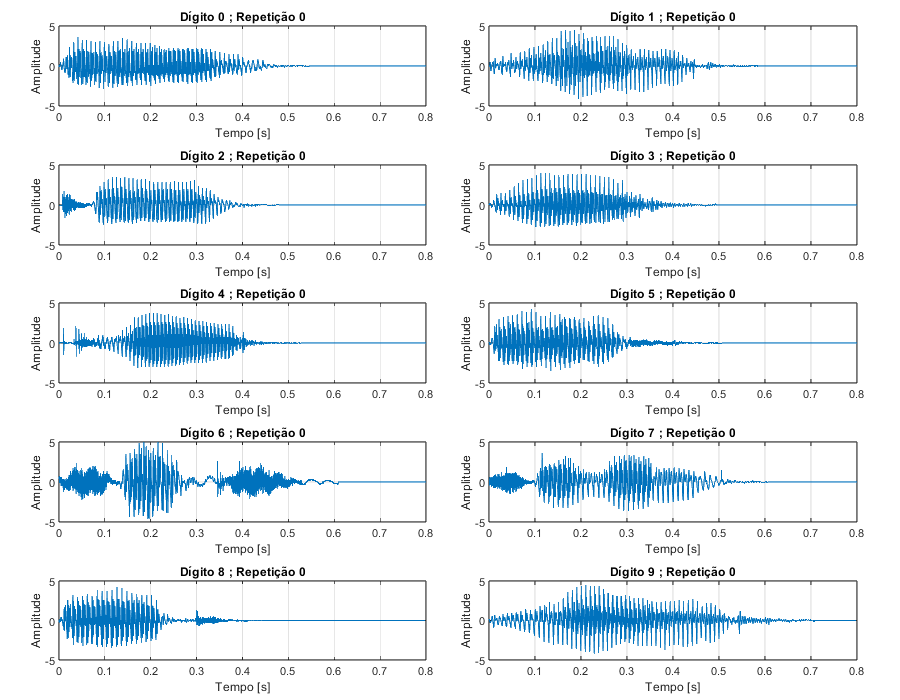

%As diferençcas entre os dois gráficos são as seguintes: o valor das amplitudes, a duração do audio e a 
% posição do grafico em relação ao tempo.
% Digitos como 1, 5, 7, 8 e 9 tem uma maior amplitude maxima, enquanto
% digitos como 2 e 4 tem uma menor amplitude maxima.

%Apresentação de todos os digitos para observar diferenças visuais dos sinais.
repeticao=0; %repeticao = input('Repeticao: ');
plotarGraficosJuntos(dados,repeticao);

7. Implemente o cálculo de possíveis características (features) temporais do sinal que permitam a diferenciação entre dígitos, como energia (total, por intervalos temporais, diferenças entre intervalos, etc.), amplitude (máxima, mínima, razão de amplitudes, desvio padrão, etc.) ou outras medidas temporais que considere relevantes.

Deverá efetuar o cálculo para cada áudio de pelo menos 5 características temporais e guardar na estrutura de dados criada no ponto 1.   

%As caracteristicas escolhidas foram: taxa de cruzamento de zero, desvio padrão, energia total, razão da amplitude e amplitude maxima.

for i = 1:numeroAudios
    sinal = dados(i).sinal;  
     
    dados(i).('taxaCruzamentoZeros') = sum(abs(diff(sign(sinal)))) / (2*length(sinal)); % 2 vezes o diff conta positivo para o negativo e vice-versa.
    dados(i).('energiaTotal') = sum(abs(sinal).^2); 
    dados(i).tAmplitudeMaxima = find(sinal == max(sinal), 1, 'first') / dados(i).taxaAmostragem;
    dados(i).('razaoAmplitude') = abs(max(sinal))/abs(min(sinal));
    dados(i).('desvioPadrao') = std(sinal);
end

%Apenas para ser apresentavel.
tabela = struct2table(dados);
tabela = sortrows(tabela, ["digito" "repeticao"]);
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    ________________    ______________    ____________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {38400×1 double}        48000               0.016523            26155  

8. Recorrendo à representação gráfica das características temporais extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Alguns exemplos são apresentados na Figura 3. Indique as características escolhidas. 

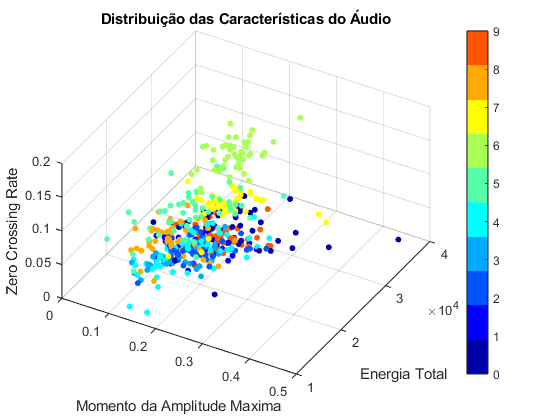

% Inicializar as caracteristicas a cruzar...
sinais = [dados.sinal];
valores1 = [dados.tAmplitudeMaxima];
valores2 = [dados.energiaTotal];
valores3 = [dados.taxaCruzamentoZeros];
digitos = [dados.digito];

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'filled');  
xlabel('Momento da Amplitude Maxima');
ylabel('Energia Total');
zlabel('Zero Crossing Rate');
grid on;
title('Distribuição das Características do Áudio');

colormap(jet(10));  
caxis([0 9])
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};

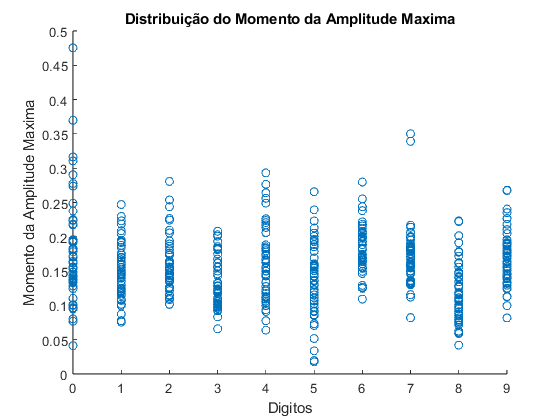

scatter(digitos,valores1,'o');
xlabel('Digitos');
ylabel('Momento da Amplitude Maxima');
title('Distribuição do Momento da Amplitude Maxima');

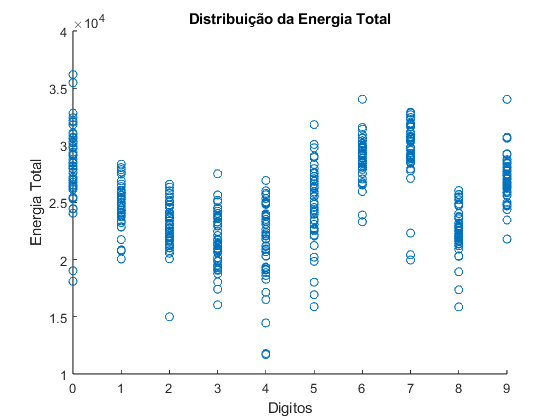

scatter(digitos,valores2,'o');
xlabel('Digitos');
ylabel('Energia Total');
title('Distribuição da Energia Total');

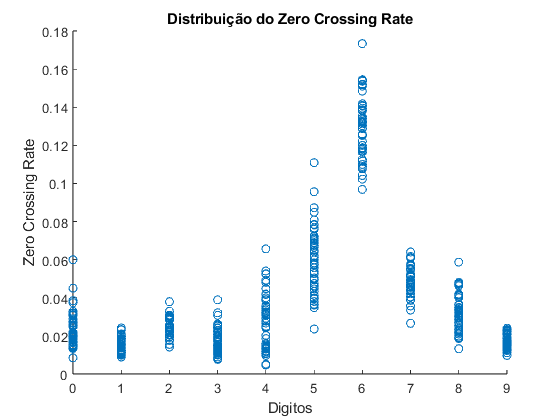

scatter(digitos,valores3,'o');
xlabel('Digitos');
ylabel('Zero Crossing Rate');
title('Distribuição do Zero Crossing Rate');

9. Remova da estrutura de dados criada no ponto 1 os sinais de áudio importados e guarde a estrutura de dados num ficheiro “.mat”.

save('dados.mat',"dados")